clc;
close all;
clear all;

%heart frequency in beats per minute
%static case
beats_vector=[53 53 53];
%dynamic case
% beats_vector=[53 63 72];

sample_time=0.5*10^(-3);
stop_time=100;%15


### Electric Parameters


%Parameters for the left ventricle from Rydeout1991mathematical
CGS_units=1332;
P_AT=6*CGS_units;
P_SV=3*CGS_units;
%resistors
R_AT=8;
R_LV=5;
R_SA=200;
R_CA=1250;
R_AO=5;
%capacitors
C_CA=0.0022;
C_AO=0.00015;
C_SA=0.0003;
Q_SAIC=281*60;%mAh
Q_LVIC=0;%120*60;%mAh
%inductors
L_AO=0.5;
L_LV=0.5;
%Generator Parameters
S_LS=2500;
S_LD=75;

%first period
T_H=1/(beats_vector(1)/60);%heart period
T_S=0.3/0.8*T_H;%duration of systole proportionally to the case when beats=75, static
B=1.05;
gen_time=0:sample_time:T_H;
gen_val=B*(S_LS-S_LD)*horzcat(sin(pi*1/T_S*(0:sample_time:T_S)),zeros(1,round((T_H-T_S)/sample_time)))+S_LD;
%clipping
gen_val(find(gen_val>=S_LS))=S_LS;

%second period
T_H2=1/(beats_vector(2)/60);%heart period
T_S2=0.3/0.8*T_H2;%duration of systole proportionally to the case when beats=75, static
gen_time2=0:sample_time:T_H2;
gen_val2=B*(S_LS-S_LD)*horzcat(sin(pi*1/T_S2*(0:sample_time:T_S2)),zeros(1,floor((T_H2-T_S2)/sample_time)))+S_LD;
if(length(gen_time2)>length(gen_val2))
    gen_val2(length(gen_val2):length(gen_time2))=zeros(1,length(gen_time2)-length(gen_val2));
end
%clipping
gen_val2(find(gen_val2>=S_LS))=S_LS;

%third period
T_H3=1/(beats_vector(3)/60);%heart period
T_S3=0.3/0.8*T_H3;%duration of systole proportionally to the case when beats=75, static
gen_time3=0:sample_time:T_H3;
gen_val3=B*(S_LS-S_LD)*horzcat(sin(pi*1/T_S3*(0:sample_time:T_S3)),zeros(1,floor((T_H3-T_S3)/sample_time)))+S_LD;
if(length(gen_time3)>length(gen_val3))
    gen_val3(length(gen_val3):length(gen_time3))=zeros(1,length(gen_time3)-length(gen_val3));
end
%clipping
gen_val3(find(gen_val3>=S_LS))=S_LS;

for i=1:ceil(stop_time*0.3/gen_time(end))
    x1=(i-1)*length(gen_val)+1;
    x2=x1+length(gen_val)-1;
    gen_val_3freqs(x1:x2)=gen_val;
end

for i=1:ceil(stop_time*0.3/gen_time2(end))
    x3=(i-1)*length(gen_val2)+1+x2;
    x4=x3+length(gen_val2)-1;
    gen_val_3freqs(x3:x4)=gen_val2;
end

for i=1:ceil(stop_time*0.3/gen_time3(end))
    x5=(i-1)*length(gen_val3)+1+x4;
    x6=x5+length(gen_val3)-1;
    gen_val_3freqs(x5:x6)=gen_val3;
end

gen_time_3freqs=(0:(length(gen_val_3freqs)-1))*sample_time;

gen_time=gen_time_3freqs;
gen_val=gen_val_3freqs;

% figure;
% plot(gen_time,gen_val); hold on
% plot(gen_time2,gen_val2);
% plot(gen_time3,gen_val3);
% figure;
% plot(gen_time_3freqs,gen_val_3freqs);

%Parameters for the arteries from noordergraaf1963use
%peripherical resistances
R_24=32.4*10^3;
R_26=64.8*10^3;
R_29=32.4*10^3;
R_34=170*10^3;
R_35=78*10^3;
R_51=R_26;
R_54=R_29;
R_59=R_34;
R_60=23.1*10^3;
R_61=10.8*10^3;
R_62=R_60;
R_64=36.8*10^3;
R_65=32.4*10^3;
R_66=69.5*10^3;
R_70=162*10^3;
R_82=126*10^3;
R_84=126*10^3;
R_88=103*10^3;
R_90=400*10^3;
R_102=R_82;
R_105=162*10^3;
R_107=R_84;
R_111=R_88;
R_113=R_90;

opts=detectImportOptions('Parameters.xlsx');
disp('Table of Parameters')

Table of Parameters


preview('Parameters.xlsx',opts) %data file preview

ans = 8×9 table
    VesselDescription    BlockNumber    SegmentID     R___     L_H__10___3_    C_F__10___9_    Length_cm_    Radius_cm_    Pressure_mmHg_
    _________________    ___________    _________    ______    ____________    ____________    __________    __________    ______________

       {0×0 char}             1          {'2a'}      0.0415        0.33            51.9           NaN           NaN          {0×0 char}  
       {0×0 char}             2          {'2b'}      0.0415        0.33            51.9           NaN           NaN          {0×0 char}  
       {0×0 char}             3          {'3a'}       0.096        0.49            33.2           NaN           NaN          


%opts.SelectedVariableNames=[1,1:6];
table=readtable('Parameters.xlsx');


[rows,colums]=size(table);
R=-ones(1,rows)';
L=-ones(1,rows)';
C=-ones(1,rows)';

for i=1:rows
    R(table2array(table(i,2)))=table2array(table(i,4));
    L(table2array(table(i,2)))=table2array(table(i,5))*10^(0);
    C(table2array(table(i,2)))=table2array(table(i,6))*10^(-6);
end

#### Simulating with the RL parameters

disp('Simulink model starts')

Simulink model starts


%running the simulink file

tic;
out_sim=sim('Noordergraaf_Rideout');
toc;

Elapsed time is 9964.266202 seconds.


save("out_noordergraaf_rideout_100s.mat","out_sim","stop_time");
disp('Saved results')

Saved results


#### Plotting results

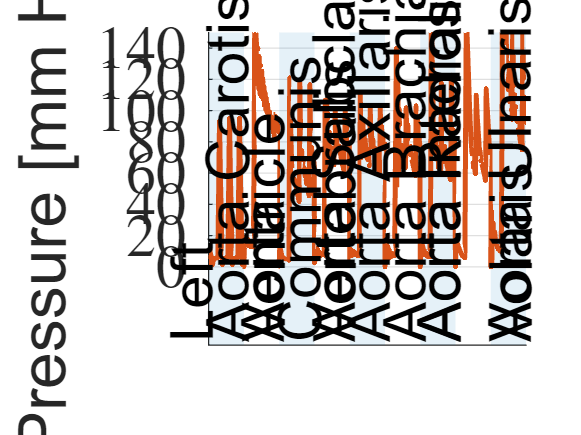

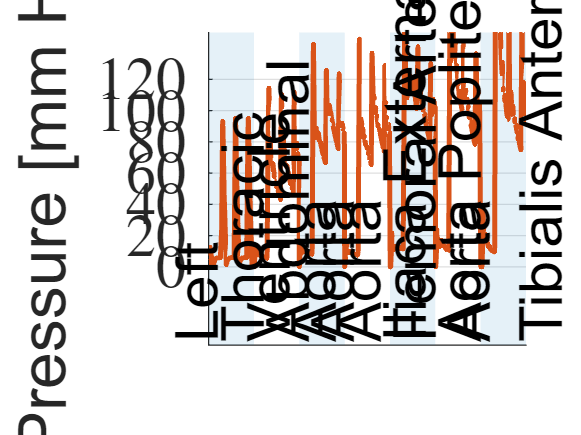

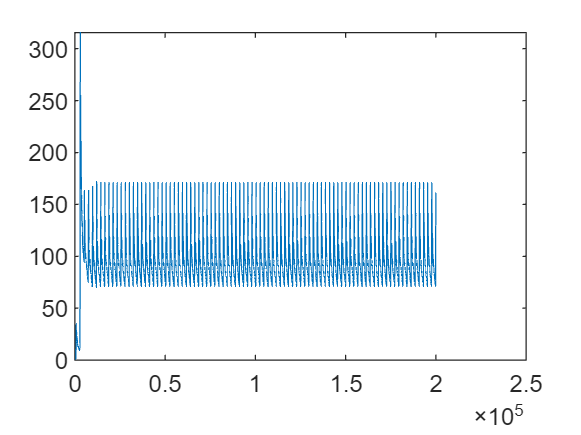

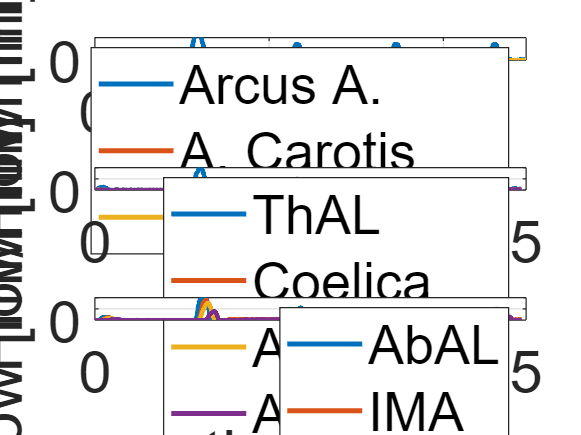

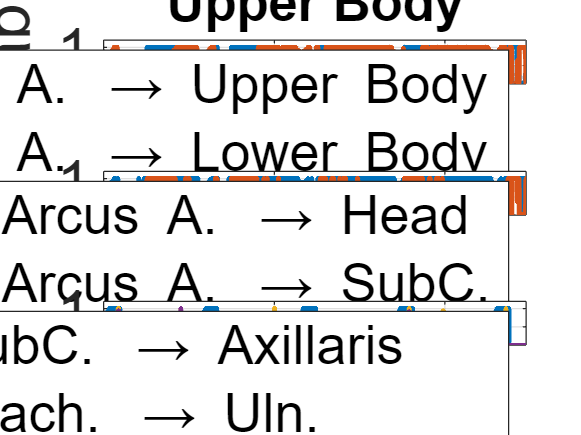

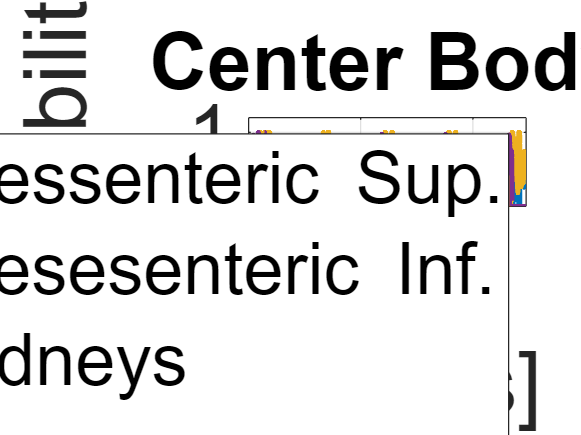

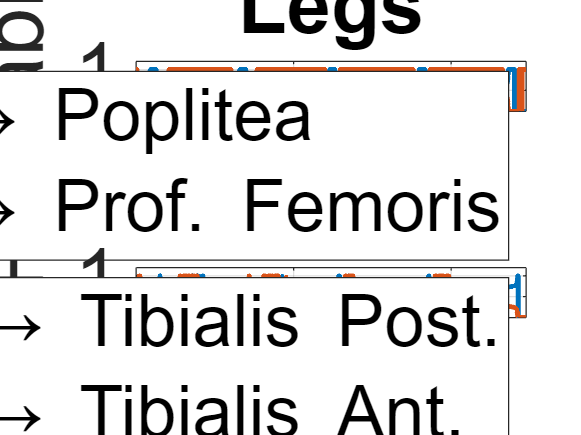

PI =      0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0  

ans = 1.0000

ans = 1

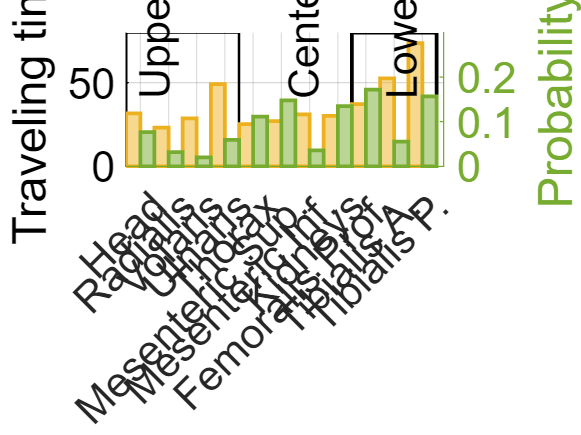

Unrecognized function or variable 'xFix_static'.

Error in B_stop_fcn_noordergraaf_rideout (line 578)
xFix=xFix_static;

% load out_noordergraaf_rideout_100s.mat
%calling to the plotting file
B_stop_fcn_noordergraaf_rideout